# Task-2

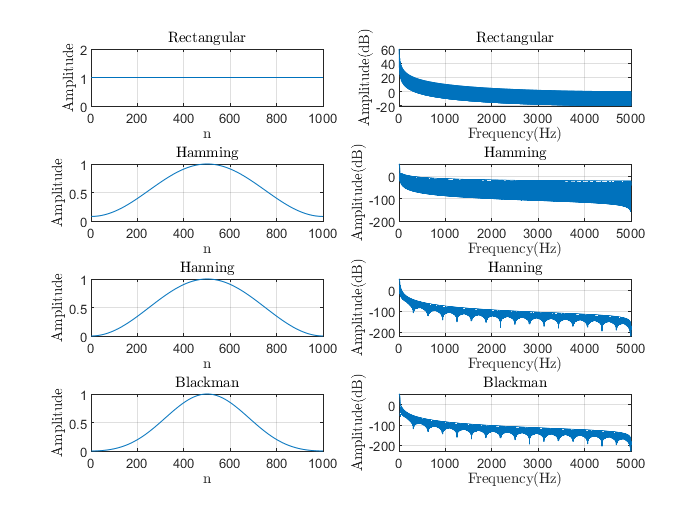

N = 1000;
Fs = 10e3;                            % Hz sample frequency
L = 32;
NFFT= L*N;
k= 0:NFFT/2-1;                        % freq index for NFFT-point FFT
f= k*Fs/NFFT;                         % Hz frequency vector
rectW = window(@rectwin, N); 
hammingW = window(@hamming, N);
hanningW = window(@hanning, N);
blackmanW = window(@blackman, N);

windowFuncs = [rectW, hammingW, hanningW, blackmanW];
windowTitle = ["Rectangular", "Hamming", "Hanning", "Blackman"];

figure;
freq = fftshift(linspace(-Fs/2, Fs/2, N));
for j=1:4
    subplot(4, 2, 2*j-1)
    win = windowFuncs(:,j)';
    plot(win);
    title(windowTitle(j), 'interpreter', 'latex');
    xlabel('n', 'interpreter', 'latex')
    ylabel('Amplitude', 'interpreter', 'latex')
    grid on;
    
    h = fft(win,NFFT);                    % FFT of length NFFT (zero padded)
    h = h(1:NFFT/2);                       % retain points from 0 to fs/2
    HdB= 20*log10(abs(h)); 
    subplot(4, 2, 2*j);
    plot(f, HdB);
    title(windowTitle(j), 'interpreter', 'latex');
    xlabel('Frequency(Hz)', 'interpreter', 'latex')
    ylabel('Amplitude(dB)', 'interpreter', 'latex')
    grid on;  
end

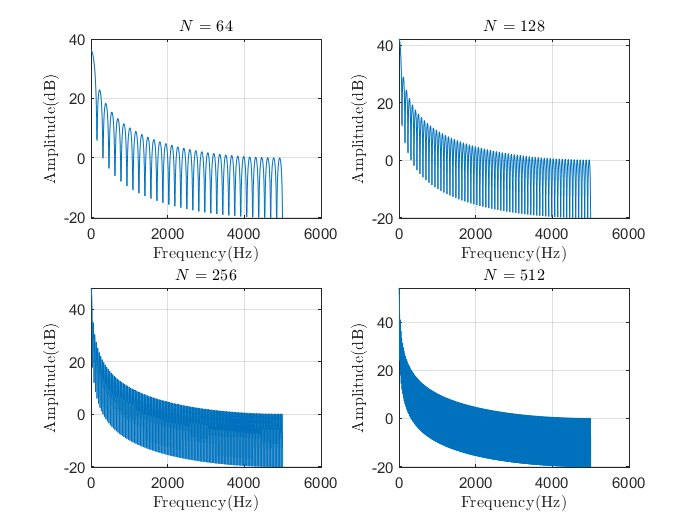



rect_wins = [];
Ns = [64, 128, 256, 512];
figure;
for j = 1:4
    win = window(@rectwin, Ns(j));
    NFFT = Ns(j)*32;
    freq = Fs/NFFT*(0:NFFT/2 - 1);
    win_fft = fft(win, NFFT);
    win_fft = win_fft(1:NFFT/2);
    win_dB = 20*log10(abs(win_fft));
    subplot(2, 2, j)
    plot(freq, win_dB);
    title(sprintf("$N = %d$", Ns(j)), 'interpreter', 'latex');
    xlabel('Frequency(Hz)', 'interpreter', 'latex')
    ylabel('Amplitude(dB)', 'interpreter', 'latex')
    grid on;  
end


disp("We can observe that as we increase N, number of sidelobes increases, which leads to larger oscilaations in output signal spectrum.");

We can observe that as we increase N, number of sidelobes increases, which leads to larger oscilaations in output signal spectrum.
